# FitAttenuation.mlx

Fits count rate versus absorber thickness for data collected with Geiger counter and sources.

Author: D. Carlsmith

### Enter data by hand

clear
x=[0.0,1.0,2.0,3.0];% absorber thickness
rate=[72, 31.28, 10.13, 1.5];% count rate
rateerr = [3.2071, 2.1141, 1.2037, 0.4738]; % count rate error

### Plot the data

errorbar(x,rate,rateerr)
title('Attenuation of rays from Sr-90')
xlabel('Thickness of Plate (mm)');ylabel('Count rate (Hz)')

### Fit the data with a maximum likelihood method including rate uncertainty.

Define model function: a constant accidental background plus an exponential. b is a set of parameters.

modelfun = @(b,t)(b(1)+b(2)*exp(-t/b(3)));

Define weights for fit.  The variance on the count in each bin is the count itself if governed by the Poisson distribution.

weights = rateerr.^(-2);% variance on conunt in each bin is count itself

Initialize/guess starting values for fit parameters. 

b0=[1,rate(1),2];

Fit the histogram data passing to `nlinfit` the data, the model function name, intial parameter values, and weights.

[beta,R,J,CovB,MSE,ErrorModelInfo] = nlinfit(x,rate,modelfun,b0, 'Weights', weights);

Print parameters and standard errors.

beta

beta =    -6.6061   79.0235    1.3145


err=sqrt(diag(CovB))

err =     1.4373
    2.0030
    0.0903


Note: We have not constrained the parameters. The constant term should be required to be positive if it represents background.

### Superpose fit on plot

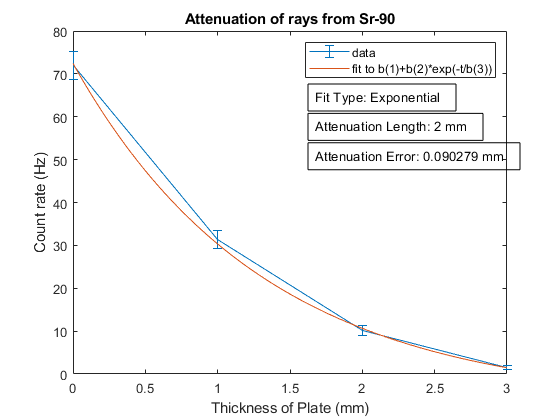

thick=[x(1):length(x)/100:x(length(x))];
Predicted=modelfun(beta,thick);
hold on
plot(thick,Predicted)
legend('data','fit to b(1)+b(2)*exp(-t/b(3))')

dim = [.55 .5 1 .3];
str = 'Fit Type: Exponential';
annotation('textbox',dim,'String',str,'FitBoxToText','on');

str = 'Attenuation Length: ' + string(b0(3)) + ' mm';
dim = [.55 .43 1 .3];
annotation('textbox',dim,'String',str,'FitBoxToText','on');


str = 'Attenuation Error: ' + string(err(3)) + ' mm';
dim = [.55 .36 1 .3];
annotation('textbox',dim,'String',str,'FitBoxToText','on');


% The annotation should indicate the kind of fit used and the derived attenuation length for beta rays from Sr in aluminum in mm with its error. 



hold off

The student should minimally replace number of plates with thickness in mm, adjust initial guess values for fit, and include fit results with units on the plot.